l = 5;
p = 4;
n = 10;
m = 20;

num_trials = 100;
num_its = 2000; % number of iterations
num_corrupt = 120; % number of corruption
k = 10 %number of corrupted rows

k = 10


%corruptions are generated from normal distribution
mean_corrupt = 100;
deviation_corrupt = 20;

errs1_matrix = zeros(num_trials, num_its+1);
errs2_matrix = zeros(num_trials, num_its+1);
% Perform trials
for t = 1:num_trials
    
    %generate tensors
    A = randn(m,l,n);
    X_true = randn(l,p,n);
    B = tprod(A,X_true);
    X_0 = randn(l,p,n);

    % Generate random corruption values for each trial
    corruption_values = mean_corrupt + deviation_corrupt*randn(num_corrupt, 1);

    % Generate k random row indices to corrupt
    corrupt_rows = randsample(m, k);
    
    % Distribute num_corrupt corruptions uniformly across the k rows
    for i = 1:num_corrupt
        % Select a random row from the chosen rows
        row_idx = corrupt_rows(randsample(k, 1));
        
        % Randomly select indices for the other dimensions
        col_idx = randsample(p, 1);
        depth_idx = randsample(n, 1);
    
        % Apply the corruption value
        B(row_idx, col_idx, depth_idx) = B(row_idx, col_idx, depth_idx) + corruption_values(i);
    end


    % Run QTRK
    q = 1-num_corrupt/(m*p*n); % quantile value
    [~,its] = QTRK_new(A,B,X_0, num_its, q);

    % Record errors for the current trial
    for j = 1:num_its + 1
        est = its{j} - X_true; % Adjust X_true according to your setup
        errs1_matrix(t,j) = norm(est(:));
    end

    % Calculate median errors across trials
    median_errs1 = median(errs1_matrix);

    %Run mQTRK
    [~,its] = mtRK_new(A,B,X_0,num_its, q);
  
    for j = 1:num_its + 1
        est = its{j} - X_true; % Adjust X_true according to your setup
        errs2_matrix(t,j) = norm(est(:));
    end

    % Calculate median errors across trials
    median_errs2 = median(errs2_matrix);
end

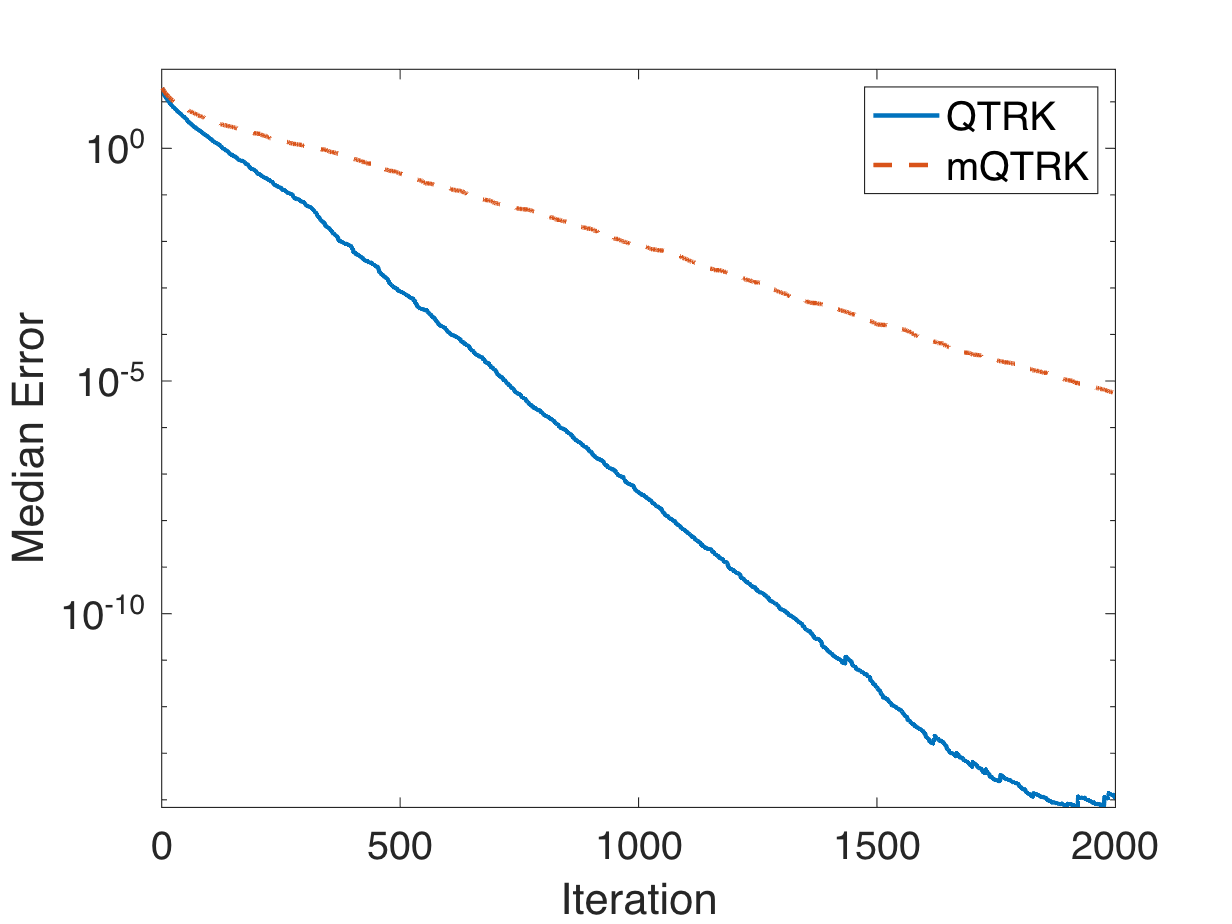

%comparison
semilogy(median_errs1,'Linewidth',2)
%title("# corruptions = " + num_corrupt)

xlabel ('Iteration', FontSize=18)
ylabel('Median Error', FontSize=18)
axis([0 num_its 0 50])
set(gca, 'FontSize', 18)
hold on

semilogy(median_errs2,'Linewidth',2, 'LineStyle', '--')

hold off

legend('QTRK','mQTRK', Location='northeast', FontSize = 18);